# maoyang / 206221321

clearvars;
Stu_ID = '206221321';
XY = mod(str2double(Stu_ID), 100);
alpha_personal = 1 + 0.002 * XY;
case_name = 'case_nongcun';
pv_buses = [4 9 14];
P_pv_peak_MW = 0.8;
dt = 1;

## 配置路径与读取数据

script_dir = fileparts(mfilename('fullpath'));
if isempty(script_dir), script_dir = pwd; end
addpath(fullfile(script_dir,'helpers'));
ess_week1_setup(script_dir);
case_dir = fullfile(script_dir,'data');
profiles = load(fullfile(case_dir,'profiles_24h.mat'));
mpc_base = loadcase(case_name);
T = double(profiles.T);
assert(T == 24, '本任务需要24个时段。');
bus_ids = mpc_base.bus(:,1);
[pv_present,pv_rows] = ismember(pv_buses,bus_ids);
assert(all(pv_present), '光伏节点不在算例中。');
mpopt = mpoption('verbose',0,'out.all',0,'pf.tol',1e-10,'pf.nr.max_it',50);
out_dir = fullfile(script_dir,'matlab_results');
if ~isfolder(out_dir), mkdir(out_dir); end

## 计算工况

load_multipliers = [1.00 1.10];
scenario_names = ["Baseline" "Load110"];
Day1 = struct('StudentID',Stu_ID,'Case',case_name,'PVNodes',pv_buses,...
    'PVPeakPerNode_MW',P_pv_peak_MW,'TimeStep_h',dt);

## 两种工况各运行24次交流潮流

for k = 1:numel(load_multipliers)
    s = struct;
    s.LoadMultiplier = load_multipliers(k);
    s.Alpha = alpha_personal * s.LoadMultiplier;
    s.Voltage_pu = zeros(numel(bus_ids), T);
    s.Loss_MW = zeros(T,1);
    s.Converged = false(T,1);
    for t = 1:T
        mpc_t = mpc_base;
        mpc_t.bus(:,3) = mpc_base.bus(:,3) * s.Alpha * profiles.load_curve_pu(t);
        mpc_t.bus(:,4) = mpc_base.bus(:,4) * s.Alpha * profiles.load_curve_pu(t);
        mpc_t.bus(pv_rows,3) = mpc_t.bus(pv_rows,3) - P_pv_peak_MW * profiles.pv_curve_pu(t);
        result = runpf(mpc_t,mpopt);
        assert(result.success == 1,'工况%s第%d时段潮流未收敛。',scenario_names(k),t);
        s.Converged(t) = true;
        s.Voltage_pu(:,t) = result.bus(:,8);
        s.Loss_MW(t) = sum(real(get_losses(result)));
    end
    [s.MinVoltage_pu,ix] = min(s.Voltage_pu(:));
    [min_row,s.MinPeriod] = ind2sub(size(s.Voltage_pu),ix);
    s.MinBus = bus_ids(min_row);
    s.DailyLoss_MWh = sum(s.Loss_MW) * dt;
    s.MaxVoltage_pu = max(s.Voltage_pu(:));
    Day1.(char(scenario_names(k))) = s;
    fprintf('%s: alpha=%.4f, Vmin=%.9f p.u., bus=%d, period=%d, loss=%.9f MWh\n',...
        scenario_names(k),s.Alpha,s.MinVoltage_pu,s.MinBus,s.MinPeriod,s.DailyLoss_MWh);
end

Baseline: alpha=1.0420, Vmin=0.954804139 p.u., bus=13, period=19, loss=1.041286065 MWh
Load110: alpha=1.1462, Vmin=0.950042860 p.u., bus=13, period=19, loss=1.178409231 MWh


## 结果表：最低电压、薄弱节点、时段与全天网损

B = Day1.Baseline;
H = Day1.Load110;
Summary = table(scenario_names', [B.Alpha;H.Alpha],...
    [B.MinVoltage_pu;H.MinVoltage_pu],[B.MinBus;H.MinBus],...
    [B.MinPeriod;H.MinPeriod],[B.DailyLoss_MWh;H.DailyLoss_MWh],...
    'VariableNames',{'Scenario','Alpha','MinVoltage_pu','MinBus','MinPeriod','DailyLoss_MWh'});
disp(Summary);

     Scenario     Alpha     MinVoltage_pu    MinBus    MinPeriod    DailyLoss_MWh
    __________    ______    _____________    ______    _________    _____________

    "Baseline"     1.042        0.9548         13         19           1.0413    
    "Load110"     1.1462       0.95004         13         19           1.1784    



writetable(Summary,fullfile(out_dir,'Day1_Summary.csv'));
selected_periods = [12;19];
Comparison = table(selected_periods,min(B.Voltage_pu(:,selected_periods),[],1)',...
    min(H.Voltage_pu(:,selected_periods),[],1)',B.Loss_MW(selected_periods),...
    H.Loss_MW(selected_periods),'VariableNames',{'Period','BaselineMinVoltage_pu',...
    'Load110MinVoltage_pu','BaselineLoss_MW','Load110Loss_MW'});
disp(Comparison);

    Period    BaselineMinVoltage_pu    Load110MinVoltage_pu    BaselineLoss_MW    Load110Loss_MW
    ______    _____________________    ____________________    _______________    ______________

      12             0.97674                 0.97435              0.090466           0.090527   
      19              0.9548                 0.95004              0.069777           0.084965   



writetable(Comparison,fullfile(out_dir,'Day1_NoonEvening.csv'));
fprintf('全天电能损耗变化: %+.4f%%\n',100*(H.DailyLoss_MWh/B.DailyLoss_MWh-1));

全天电能损耗变化: +13.1686%


## 任务一结果图

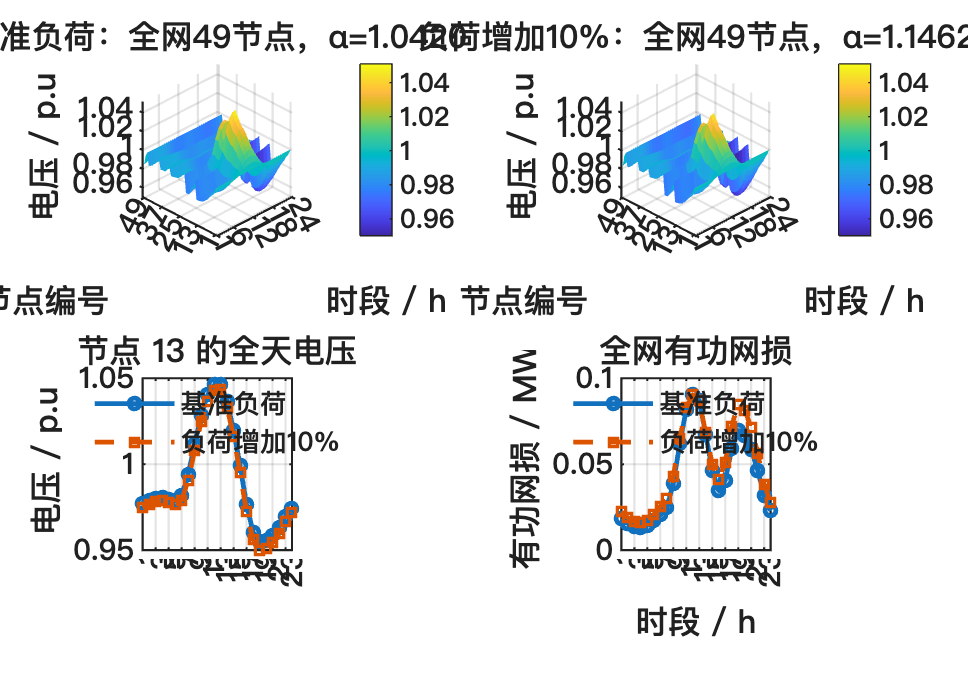

ess_week1_figure(1,struct('Day1',Day1),script_dir);

## 保存结果

Day1.Summary = Summary;
Day1.NoonEvening = Comparison;
summary_file = fullfile(script_dir,'result_summary.mat');
if isfile(summary_file)
    save(summary_file,'Day1','-append');
else
    save(summary_file,'Day1');
end